# **LABORATORIO 2 ROBOTICA**

**UNIVERSIDAD NACIONAL DE COLOMBIA**

### **Aristides Daniel Cantero Castillo**

### **Farid Alexis Estepa Quintero **

### **William Andrés Castillo Bautista**

**15 de diciembre del 2021**

**Punto 1**

Para la resolución del problema se descartó la realización del método de desacople cinemático debido que el robot ABB CRB 15000 no posee muñeca esférica, sino con offset, como se aprecia en la imagen:

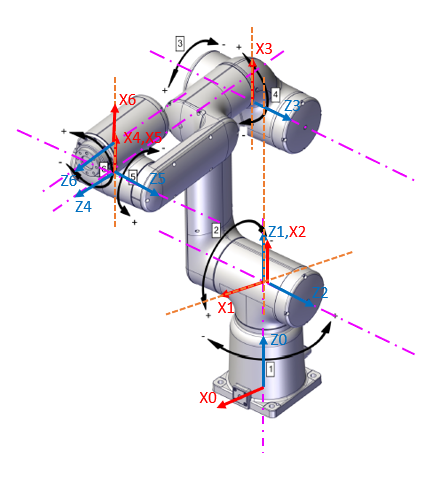

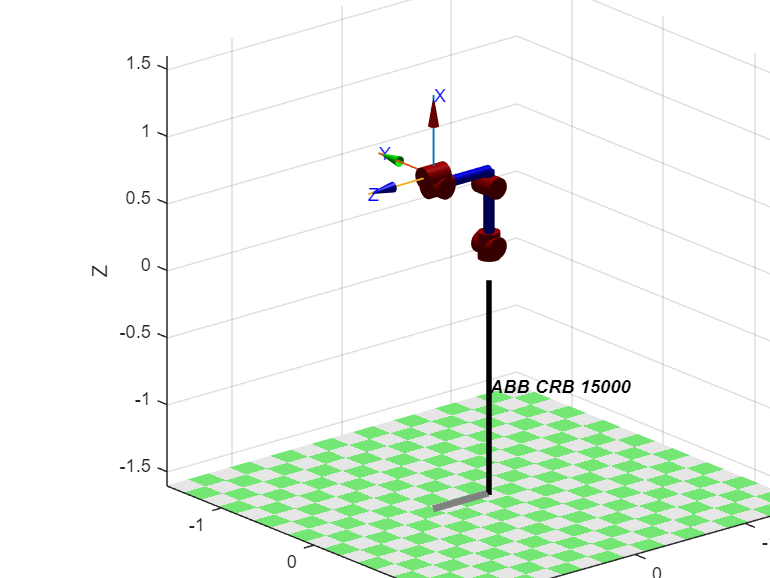

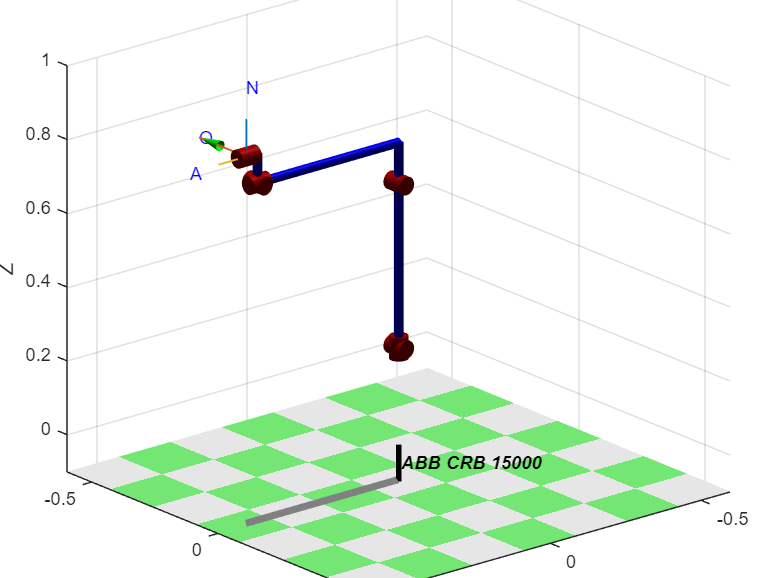

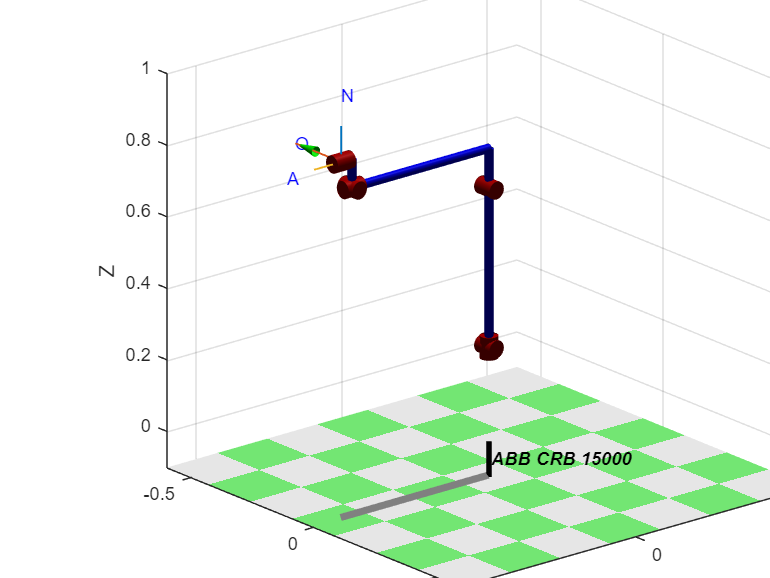

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 
%Se plotea el robot, para ciertos ángulos theta.

Robot_ABB.plot([0 0 0 0 0 0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

Para resolver el robot se decidió posteriormente realizar un análisis de la ecuación matricial entre las transformaciones de las articulaciones y la matriz final, con el objetivo de obtener ecuaciones en términos capaces de ser despejados.

### Matrices de transformación homogenea

T_0_1=L(1).A(theta_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2=L(2).A(theta_2);
T_1_2=[cos(theta_2-pi/2) -sin(theta_2-pi/2) 0 0
    0 0 1 0
    -sin(theta_2-pi/2) -cos(theta_2-pi/2) 0 0
    0 0 0 1]

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}-\frac{\pi }{2}\right) & -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & -\cos\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3=L(3).A(theta_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{111}{250}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_4=L(4).A(theta_4);
T_3_4=[cos(theta_4) -sin(theta_4) 0 11/100
    0 0 1 47/100
    -sin(theta_4) -cos(theta_4) 0 0
    0 0 0 1]

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{11}{100}\\ 0 & 0 & 1 & \frac{47}{100}\\ -\sin\left(\theta_{4}\right) & -\cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_4_5=L(5).A(theta_5);
T_4_5=[cos(theta_5) -sin(theta_5) 0 0
    0 0 -1 0
    sin(theta_5) cos(theta_5) 0 0
    0 0 0 1]

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_5_6=L(6).A(theta_6);
T_5_6=[cos(theta_6) -sin(theta_6) 0 2/25
    0 0 1 37/1000
    -sin(theta_6) -cos(theta_6) 0 0
    0 0 0 1]

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & \frac{2}{25}\\ 0 & 0 & 1 & \frac{37}{1000}\\ -\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_0_6=T_0_1*T_1_2*T_2_3*T_3_4*T_4_5*T_5_6
%Robot_ABB.plot([0,0,0,0,0,0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])


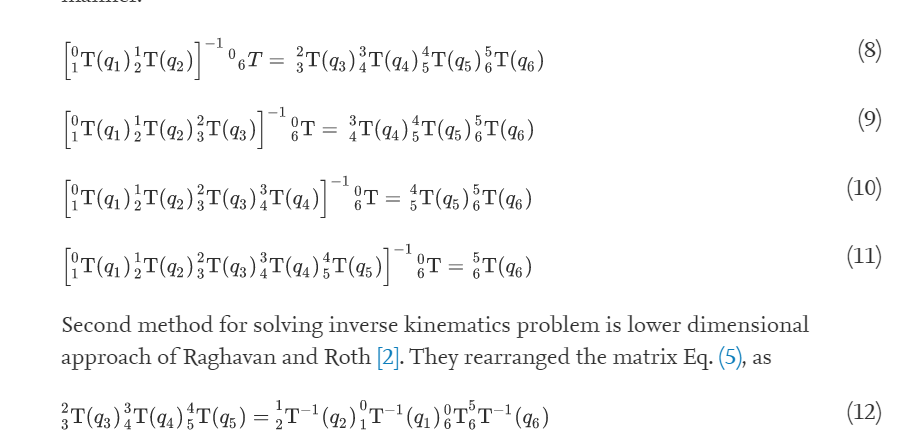

 Las ecuación más viable a despejar es la ecuación 9, en la cual se obtiene la forma: 

syms r11 r12 r13 r21 r22 r23 r31 r32 r33 px py pz
R=[r11 r12 r13 
   r21 r22 r23
   r31 r32 r33];
p=[px;   py;    pz];
T_0_6=[R,p;0 0 0 1];

T_3_4*T_4_5*T_5_6

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & \frac{2\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)}{25}-\frac{37\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)}{1000}+\frac{11}{100}\\ \cos\left(\theta_{6}\right)\,\sin\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{5}\right) & \frac{37\,\cos\left(\theta_{5}\right)}{1000}+\frac{2\,\sin\left(\theta_{5}\right)}{25}+\frac{47}{100}\\ -\cos\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)-\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right) & \cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{6}\right) & \sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & \frac{37\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)}{1000}-\frac{2\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)}{25}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

inv(T_2_3)*inv(T_1_2)*inv(T_0_1)*T_0_6

sin embargo, se puede apreciar en todas las columnas y filas de la igualdad matricial ecuaciones trigonométricas de 3 variables, las cuales no están dentro de los recursos y herramientas para el curso y por otro lado son muy extensas y de orden muy alto para resolverlas, inclusive con cambio de variable, por este motivo se descartó completamente la idea.

# Método utilizado

Para resolver el robot es de destacar que la articulación número 4 genera inconventes a la hora de resolver la cinemática inversa, ya que aumenta el orden de las variables que se pueden despejar y geométricamente altera todas las variables de la pose del efector, es por esto que se ha decidido restringir esta variable y aprovechar el método geométrico basado en esta suposición. Con esto en mente, se definde $\theta_4 :=0$.

## Método geométrico para las 3 primeras articulaciones

Al restringir la 4ta articulación, se puede reevaluar el robot geométricamente de la siguiente forma:

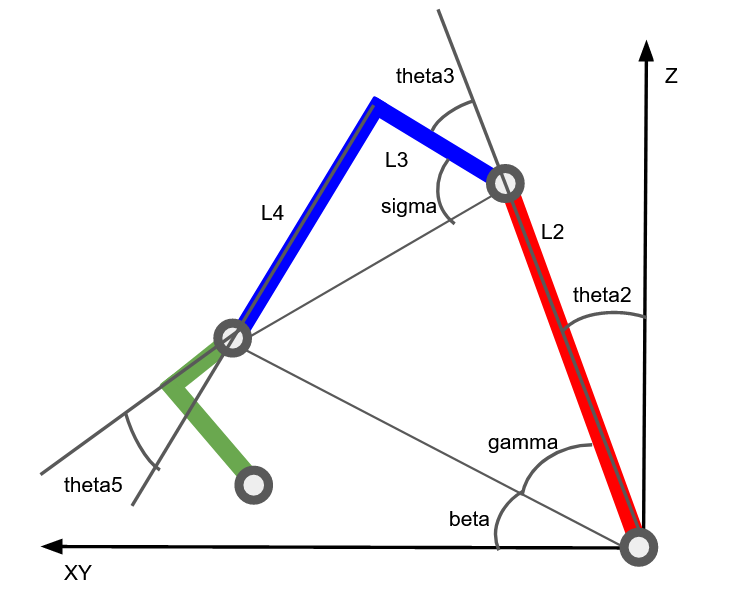

Para la facilidad de los cálculos, se realiza una transformación que mueve la pose del efector final hasta la articulación 5, basados en las traslaciones desde 6 a 5 con ayuda del vector:

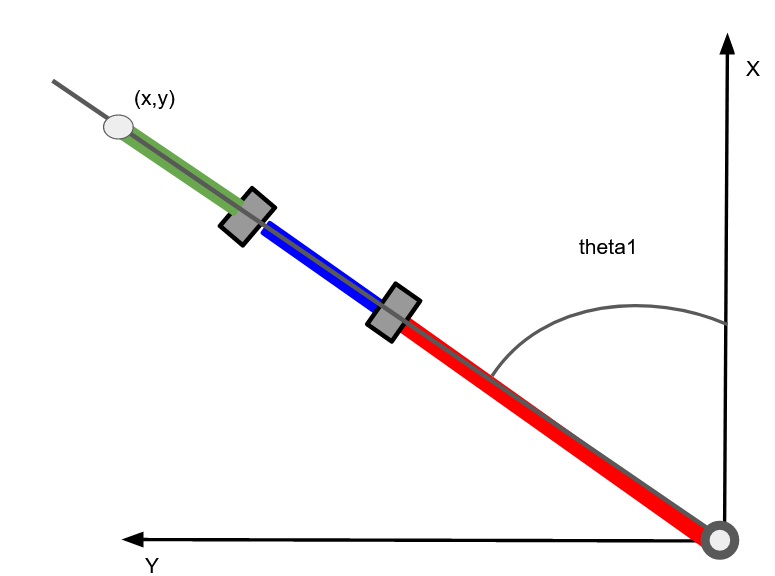

Para la facilidad de los cálculos, se realiza una transformación que mueve desde la posición del efector final hasta la articulación 5, basados en las traslaciones desde 6 a 5 con ayuda del vector:


$$P\_65=\left\lbrack \begin{array}{c}
-\cos \left(\mathrm{q1}\right)\\
\mathrm{L6}-\sin \left(\mathrm{q1}\right)\\
\mathrm{L6}-\mathrm{L5}
\end{array}\right\rbrack$$


Sin embargo, debido a la necesidad de conocer theta1, se debe calcular este primero, por lo cual se calcula partiendo de la posición en X y Y del efector final, las cuales como se aprecian en la figura aunque no permitan determinar el valor de forma inmediata del resto de articulaciones, como solamente theta1 puede variar el ángulo visto desde Z, permite el cálculo inmediato:


$$\Theta_1 =\mathrm{atan2}\left(\frac{Y}{X}\right)$$


Posteriormente se trabaja en el plano perpendicular a la segunda imagen y que contiene al robot, de forma que se puede evaluar la vista lateral del robot con la 4ta articulación bloqueada, el primer valor calculable es theta2, el cual cumple la condición: $\Theta_2 +\Upsilon +\beta =90°$

Para las cuales  $\Upsilon$ se obtiene al resolver el teorema del coseno entre las articulaciones 2, 3 y 4 y $\beta$ se obtiene al resolver el ángulo entre el efector final, la articulación 2 y la recta originada de la intersección del plano del robot con el plano XY:


$$L_3^2 +L_4^2 =L_2^2 +x^2 +y^2 +z^2 -2*L_2 *\sqrt{x^2 +y^2 +z^2 }*\cos \left(\Upsilon \right)$$



$$\textrm{acos}\left(\frac{L_3^2 +L_4^2 -\left(L_2^2 +x^2 +y^2 +z^2 \right)\;}{-2*L_2 *\sqrt{x^2 +y^2 +z^2 }}\right)=\Upsilon$$
        
$$\beta =\textrm{atan2}\left(\frac{\sqrt{x^2 +y^2 }}{z^2 }\right)$$
 

Con estos valores se determina  $\Theta_2 =90°$$-\Upsilon -\beta$

Siguiente, y aprovechando el ángulo de 180 grados por la recta que pasa por las articulaciones 2 y 3: $180°\;=\Theta_3 +\sigma +\alpha$, se aprovecha el teorema del coseno para obtener alfa y sigma de obtiene al conocer las longitudes L3 y L4:


$${\;x^2 +y^2 +z^2 =L}_3^2 +L_4^2 +L_2^2 +-2*L_2 *\sqrt{{\;L}_3^2 +L_4^2 }*\cos \left(\alpha \right)$$
 


$${\;\textrm{acos}\left(\frac{x^2 +y^2 +z^2 -\left(L_3^2 +L_4^2 +L_2^2 \right)}{-2*L_2 *\sqrt{{\;L}_3^2 +L_4^2 }}\right)=\alpha }$$
   
$$\sigma =\mathrm{atan2}\left(\frac{L_4 }{L_3 }\right)$$


Al reemplazar en la expresión original: $180°-\textrm{atan2}\left(\frac{L_4 }{L_3 }\right)-\alpha =\Theta_3$ se obtiene theta3

## Calculo de las articulaciones finales

Para el cálculo de las articulaciones 5 y 6 se parte de la condición de restricción de theta_4 y la siguiente configuración geométrica del robot

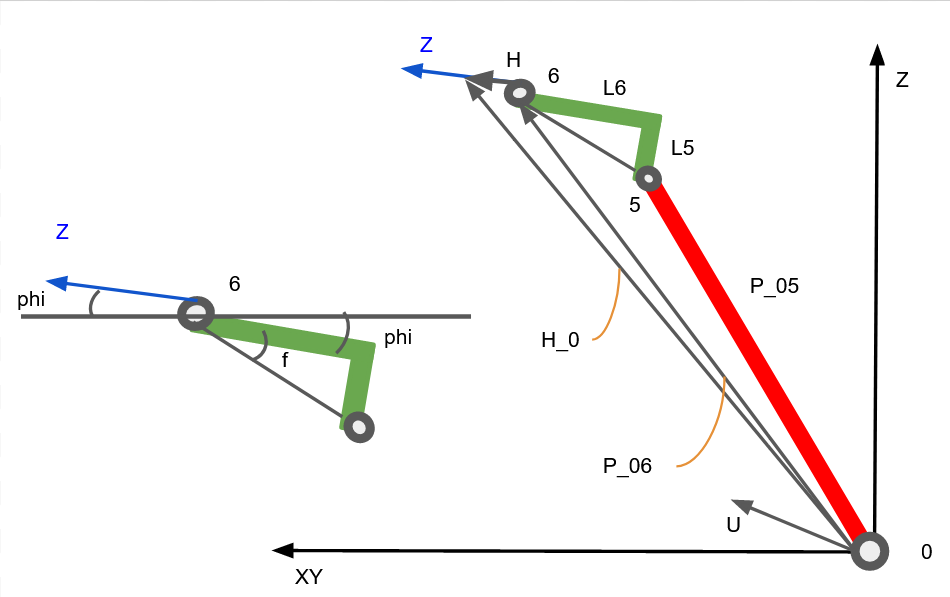

Para hallar la dirección que debe seguir el efector final se parte de la búsqueda de su inclinación respecto el plano XY, el cual se describe como el ángulo phi, partiendo de un vector unitario que une la articulación 6 con esta dirección se tiene:

${}^6H=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack$ y se pueden relacionar las transformaciones de origen y final por medio de la expresión: ${}^0H={}^0T_6\;{}^6P$y también se puede relacionar la pose final con la articulación 6 por la expresión: $\overrightarrow{U} ={}^0H-{}^0P_6$

por medio de estos despejes se conoce el vector U que sigue el recorrido de Z y con este se puede conocer el ángulo phi y los ángulos adyacentes:


$$\varphi =\mathrm{atan2}\left(\frac{\overrightarrow{U} \left(3\right)}{\sqrt{\overrightarrow{U} {\left(1\right)}^2 +\overrightarrow{U} {\left(2\right)}^2 }\;}\right)$$
   
$$f=\textrm{atan2}\left(\frac{\textrm{L5}}{\textrm{L6}}\right)$$
        
$$h=f+\varphi$$


Al conocer estos ángulos podemos determinar el vector de desplazamiente entre 6 y 5 como:

${}^6P_5=\left\lbrack \begin{array}{c}
\cos \left(\mathrm{q1}\right)\left(\cos \left(h\right)\sqrt{L_5^2 +L_6^2 }\right)\\
\sin \left(\mathrm{q1}\right)\left(\sin \left(h\right)\sqrt{L_5^2 +L_6^2 }\right)\\
\left(\sin \left(h\right)\sqrt{L_5^2 +L_6^2 }\right)
\end{array}\right\rbrack$  para  $q_5 ={-q}_2 -q_3$

Apreciando el robot como la transformación desde la articulación 0 hasta la 5 y de la 5 a la 6 se obtiene el sigueinte esquema:

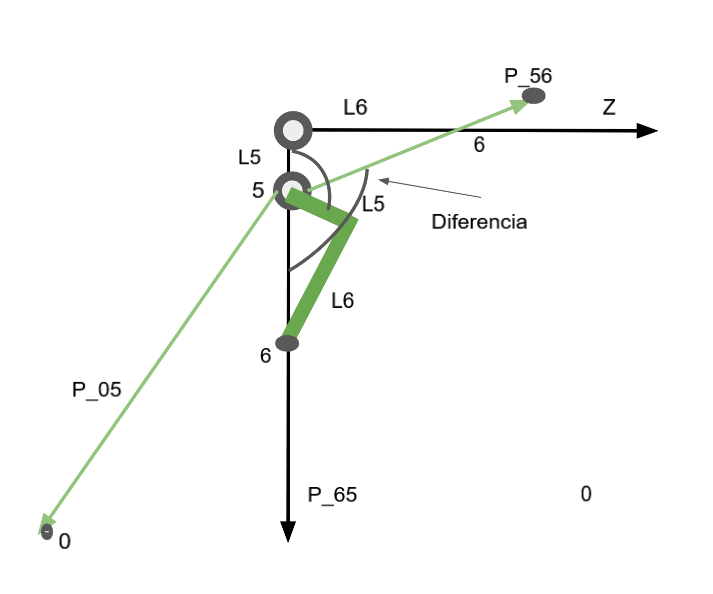

en el cual se puede deducir el vector de 5 a 6, y q5 a aprtir de las expresiones:


$${}^5P_6=\left\lbrack \begin{array}{c}
\cos \left(\mathrm{q1}\right)L_6 \\
\sin \left(\mathrm{q1}\right)L_6 \\
L_5 
\end{array}\right\rbrack$$
   
$${\textrm{ang}}_0 =\textrm{atan2}\left(\frac{{}^6P_5\left(1\right)}{\sqrt{{}^6P_5{\left(1\right)}^2 +{}^6P_5{\left(2\right)}^2 }}\right)$$
 
$${\mathrm{ang}}_1 =\mathrm{atan2}\left(\frac{{}^5P_6\left(1\right)}{\sqrt{{}^5P_6{\left(1\right)}^2 +{}^5P_6{\left(2\right)}^2 }}\right)$$


La diferencia entre los dos ángulos dará la diferencia (ang1-ang0), marcada en la imagen, y para determinar q5 es equivalente a: $q_5 =\textrm{diferencia}-\left(q_2 +q_3 \right)$

Finalmente, se realiza la matriz de transformación entre 5 y 6 con la formula de transformaciones sucesivas:

${}^0T_6={}^0T_1{}^1T_2{}^2T_3{}^3T_4{}^4T_5{}^5T_6$, en la cual se despejan q1, q2, q3 y q5 con los valores que se calcularon, q4 se mantiene en cero y q6 se mantiene momentaneamente como cero también, de esta forma se tiene una matriz homogenea que cumple la dirección Z pero no las otras dos componentes del RPY, para esto se calcula de la forma:

$\textrm{RPY}=\textrm{tr2rpy}\left({}^0T_6\right)=\left\lbrack \begin{array}{c}
R\\
P\\
Y
\end{array}\right\rbrack$  de esta para determinar el valor de q6 se calcula el desfase actual entre la configuración que se tiene y la deseada:  $q_6 =Y-Y_{\mathrm{deseado}}$